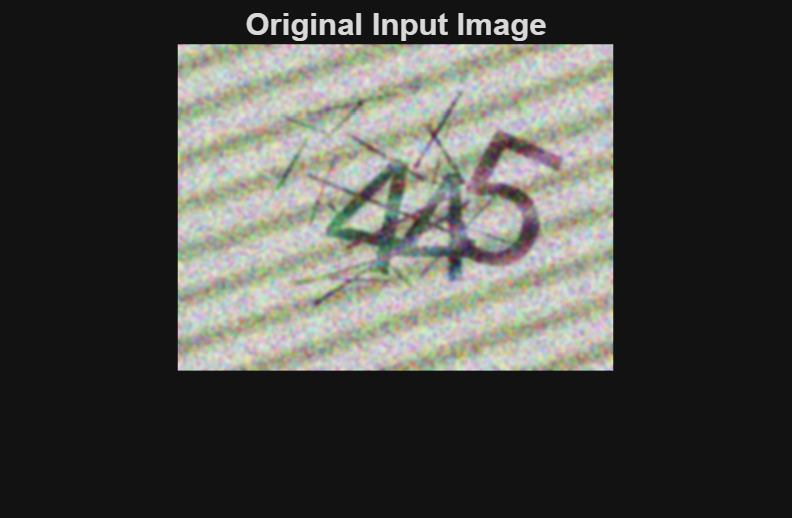

clc; clear; close all;

I = imread('Train/captcha_0456.png');

figure;
imshow(I);
title('Original Input Image');

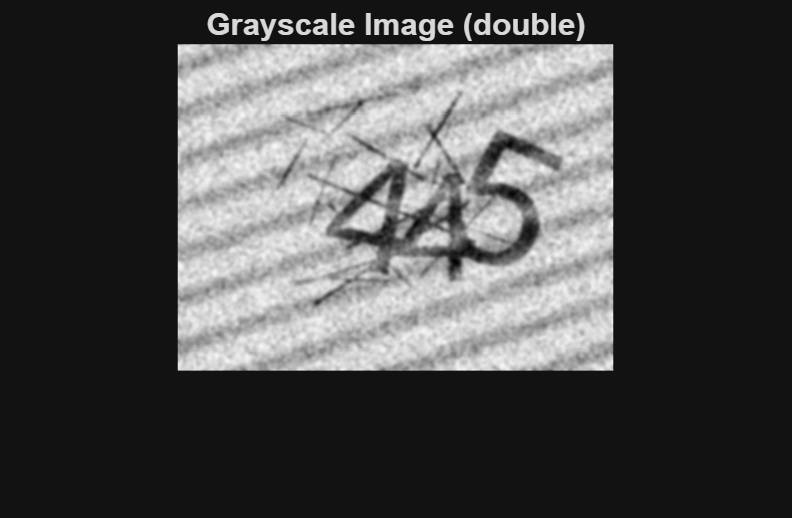

if size(I,3) == 3
    G = rgb2gray(I);
else
    G = I;
end

G = im2double(G);

figure;
imshow(G,[]);
title('Grayscale Image (double)');

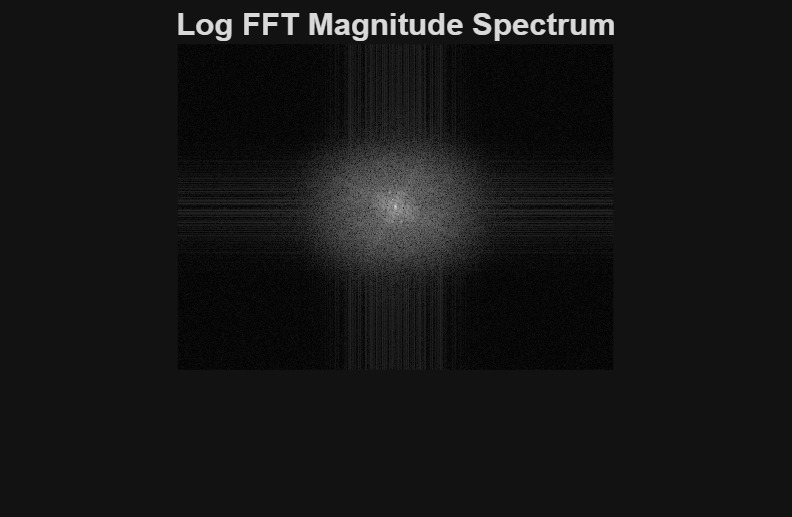

F  = fft2(G);
Fs = fftshift(F);
Mag = abs(Fs);

figure;
imshow(log(1+Mag),[]);
title('Log FFT Magnitude Spectrum');

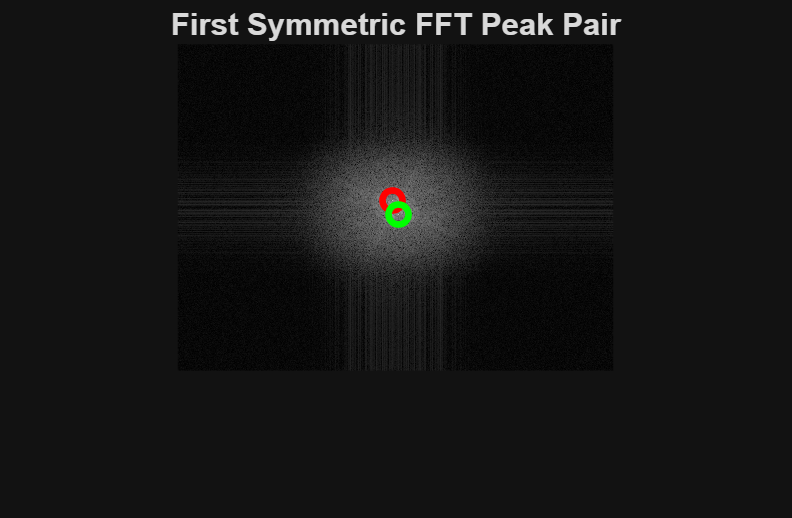

[H,W] = size(G);
cx = floor(W/2)+1;
cy = floor(H/2)+1;

r_min = 5;
r_max = 100;

[X,Y] = meshgrid(1:W,1:H);
R = sqrt((X-cx).^2 + (Y-cy).^2);

cand = (R>=r_min) & (R<=r_max);
V = Mag;
V(~cand) = -Inf;

[~, idx] = max(V(:));
[y,x] = ind2sub([H,W], idx);

pA = [x y];
pA_sym = [2*cx-x, 2*cy-y];

figure;
imshow(log(1+Mag),[]); hold on;
plot(pA(1),pA(2),'ro','LineWidth',2);
plot(pA_sym(1),pA_sym(2),'go','LineWidth',2);
title('First Symmetric FFT Peak Pair');

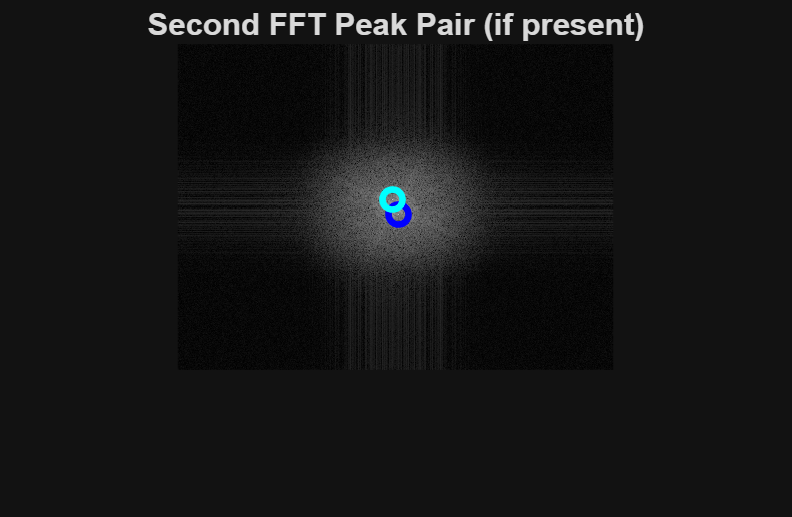

v = pA - [cx cy];
v = v / norm(v);

t = (-max(H,W):max(H,W));
xs = round(cx + t*v(1));
ys = round(cy + t*v(2));

valid = xs>=1 & xs<=W & ys>=1 & ys<=H;
xs = xs(valid); ys = ys(valid);

Rline = sqrt((xs-cx).^2 + (ys-cy).^2);
keep = (Rline>=r_min & Rline<=r_max);

xs = xs(keep); ys = ys(keep);
scores = Mag(sub2ind([H,W],ys,xs));

% suppress first peak
scores((xs-pA(1)).^2 + (ys-pA(2)).^2 <= 4) = -Inf;

[m,idx2] = max(scores);

figure;
imshow(log(1+Mag),[]); hold on;
plot(xs(idx2),ys(idx2),'bo','LineWidth',2);
plot(2*cx-xs(idx2),2*cy-ys(idx2),'co','LineWidth',2);
title('Second FFT Peak Pair (if present)');

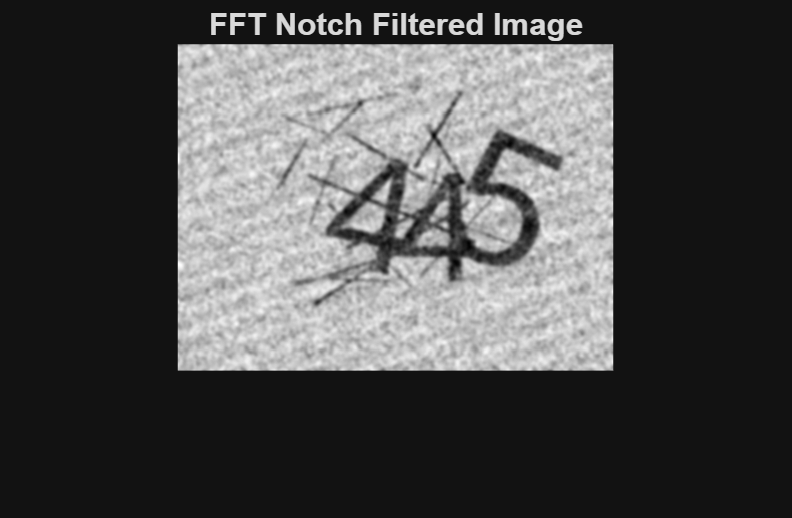

notchRadius = 2;
mask = true(H,W);

[X,Y] = meshgrid(1:W,1:H);

peaks = [pA; pA_sym];

for k = 1:size(peaks,1)
    disk = (X-peaks(k,1)).^2 + (Y-peaks(k,2)).^2 <= notchRadius^2;
    mask(disk) = 0;
end

Fs_filt = Fs .* mask;
Gclean = real(ifft2(ifftshift(Fs_filt)));
Gclean = mat2gray(Gclean);

figure;
imshow(Gclean,[]);
title('FFT Notch Filtered Image');

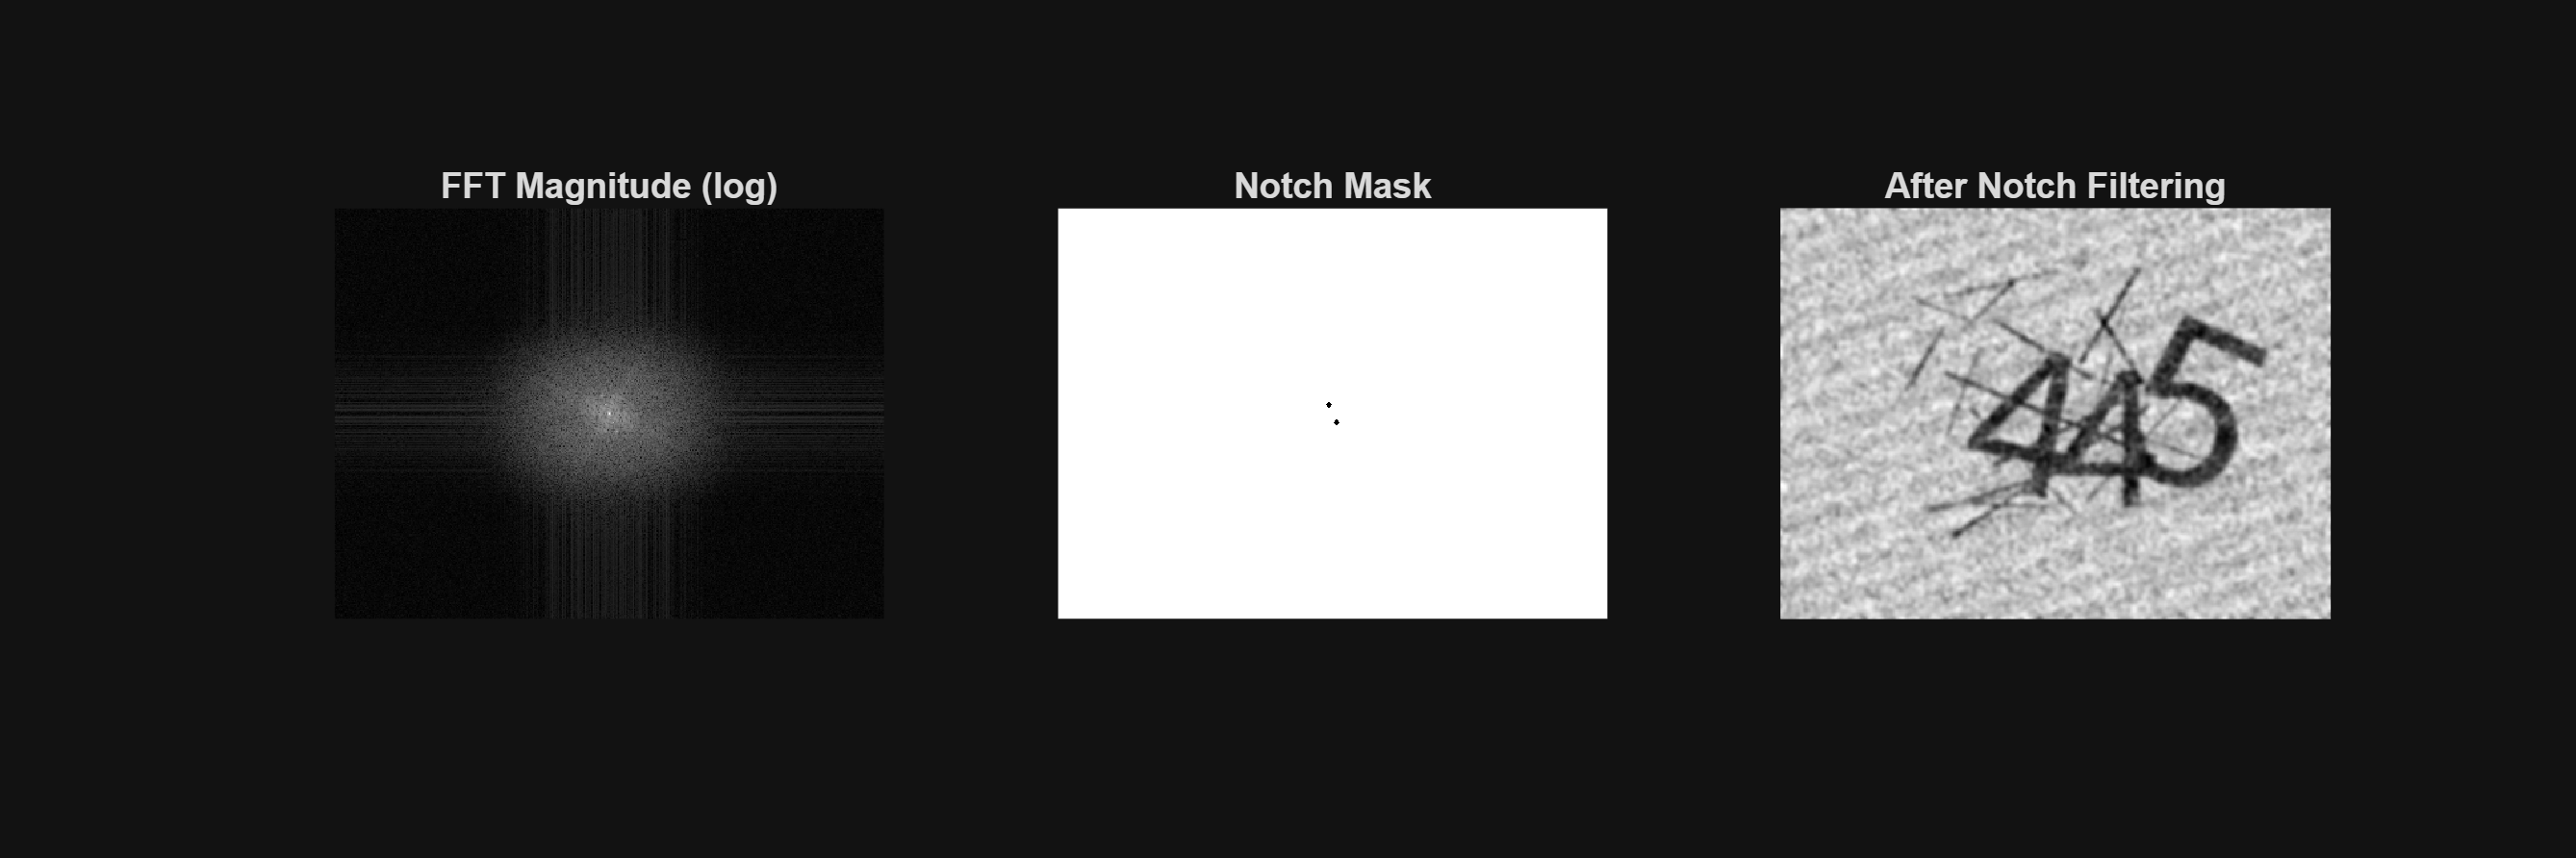

figure('Name','Step 5: FFT Notch Filtering','Position',[100 100 1200 400]);

subplot(1,3,1);
imshow(log(1+Mag),[]);
title('FFT Magnitude (log)');

subplot(1,3,2);
imshow(mask);
title('Notch Mask');

subplot(1,3,3);
imshow(Gclean,[]);
title('After Notch Filtering');

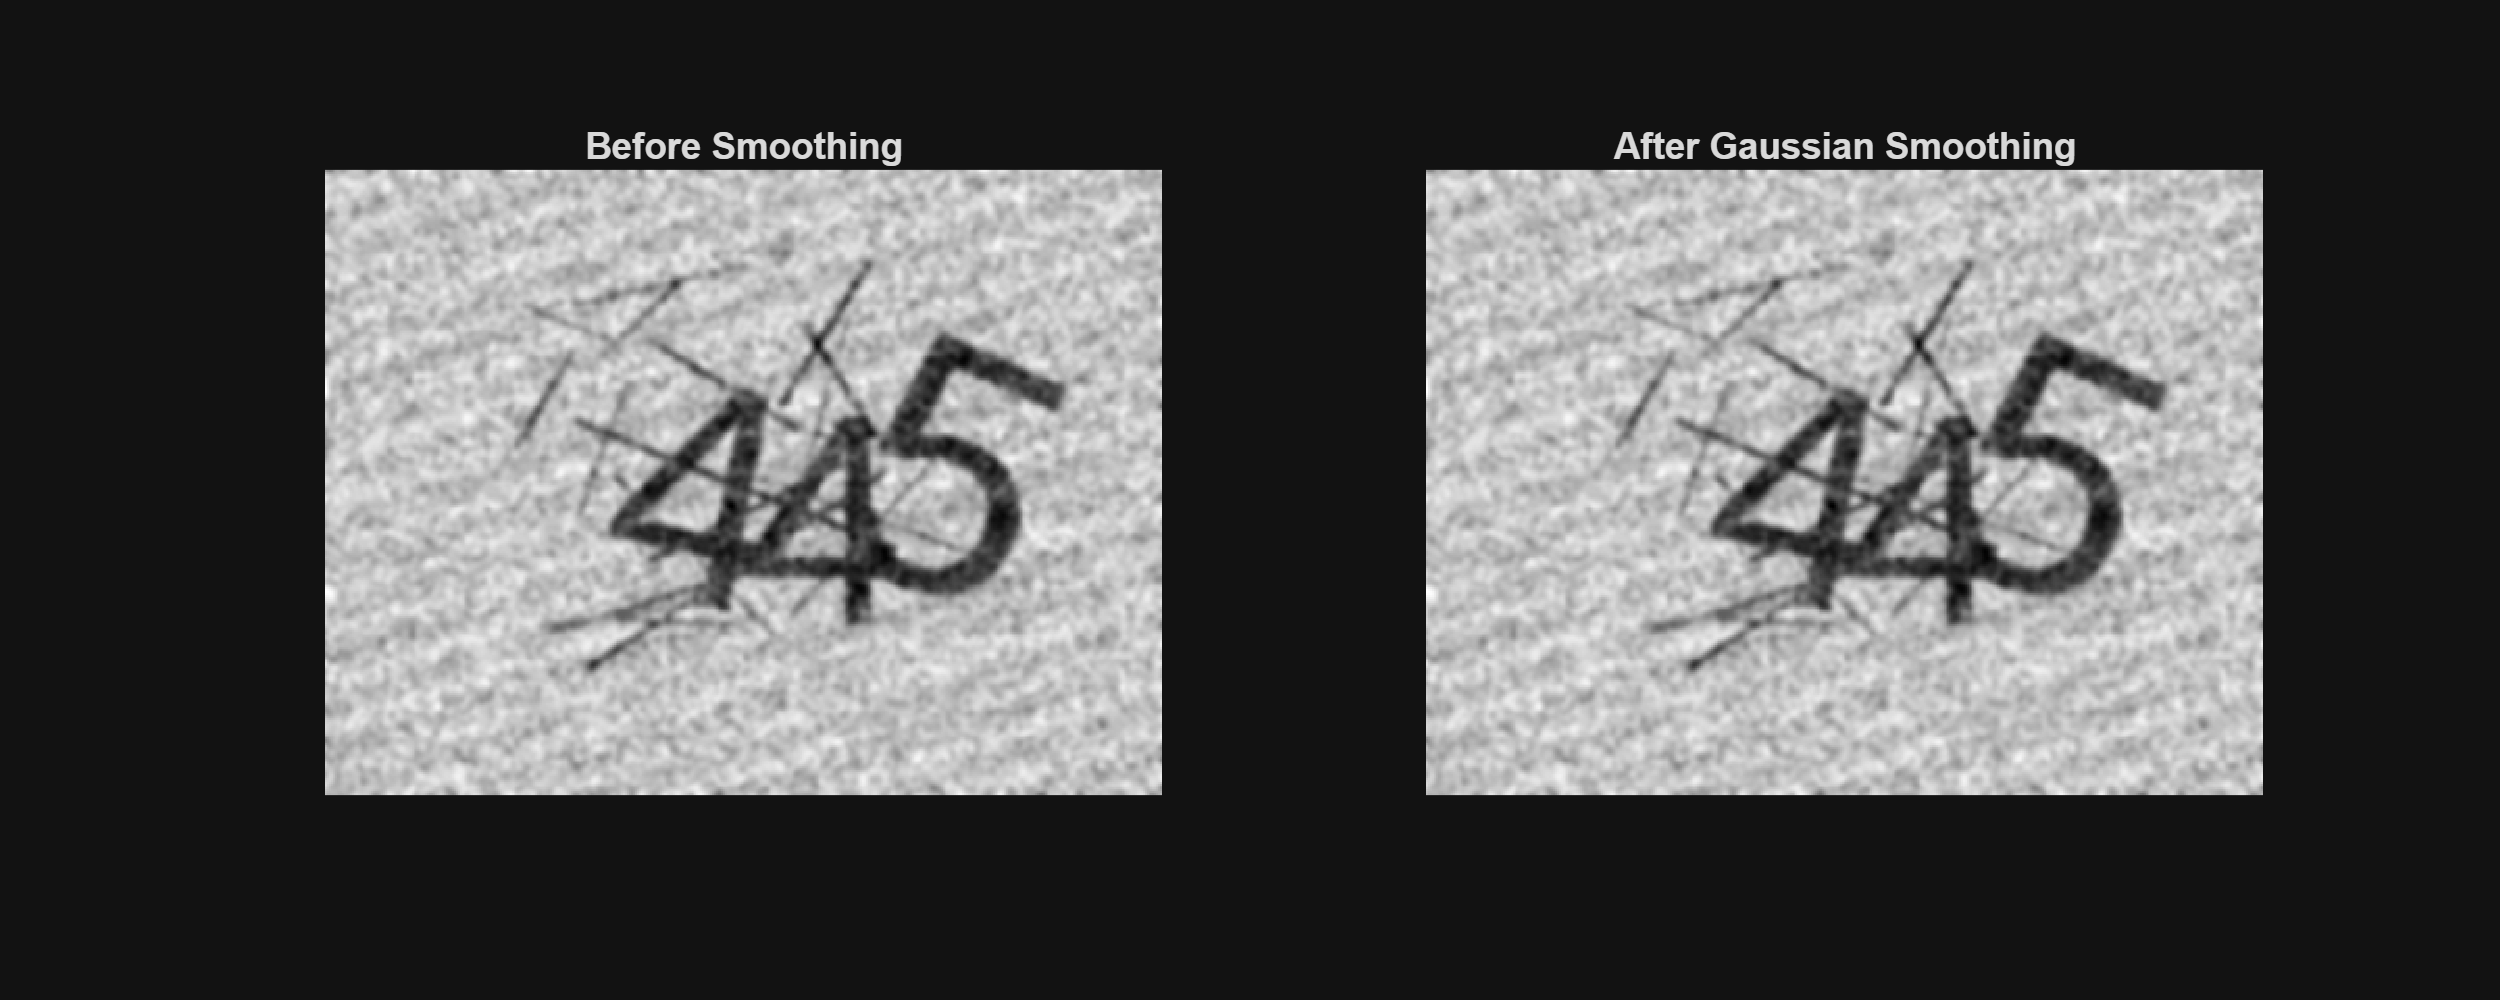

figure('Name','Step 6: Gaussian Smoothing','Position',[100 100 1000 400]);

subplot(1,2,1);
imshow(Gclean,[]);
title('Before Smoothing');

sigma = 0.17;
Gclean = imgaussfilt(Gclean, sigma);

subplot(1,2,2);
imshow(Gclean,[]);
title('After Gaussian Smoothing');

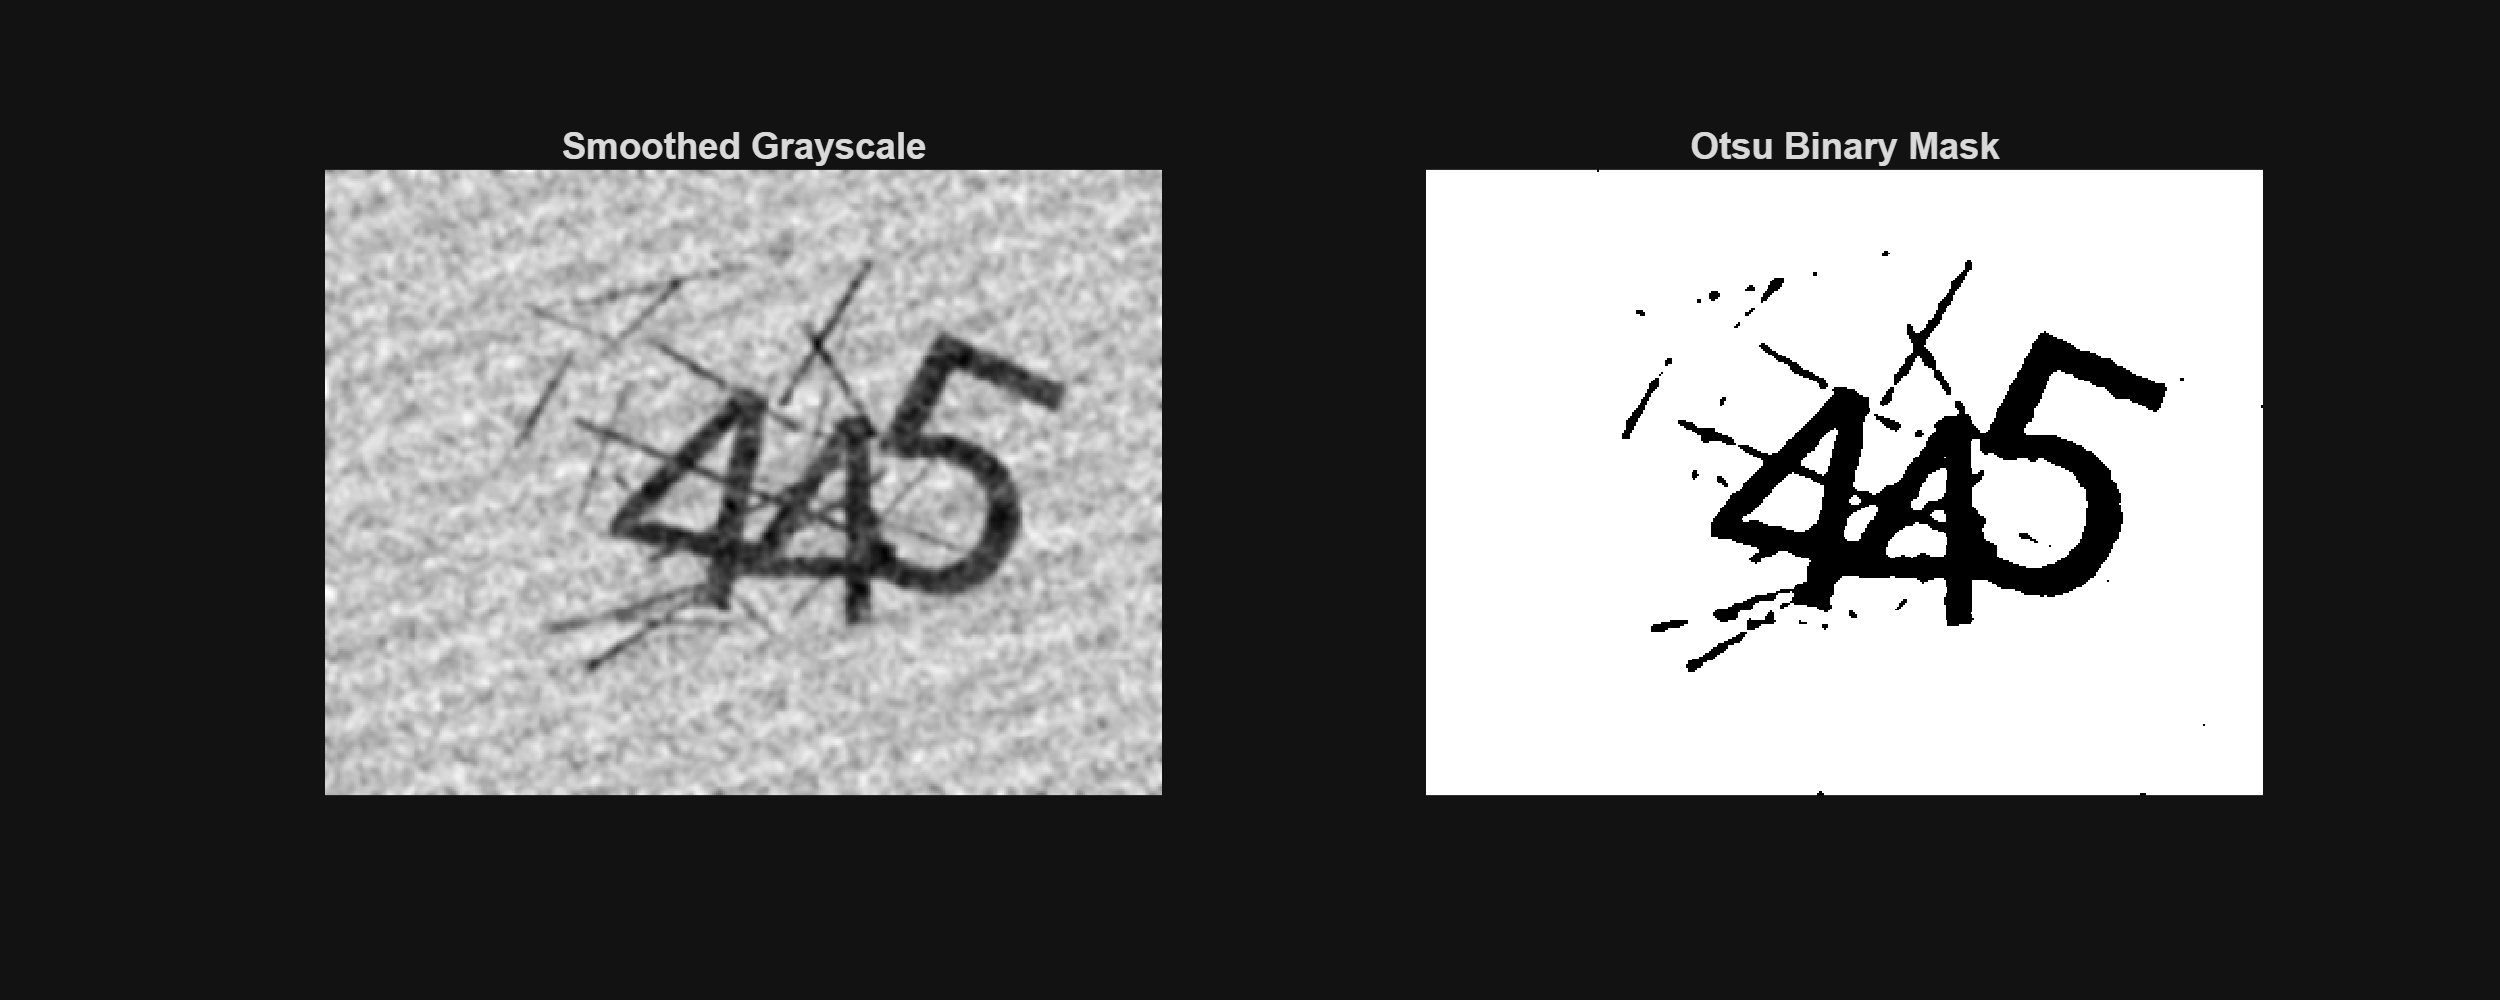

BW_otsu = imbinarize(Gclean, graythresh(Gclean));

figure('Name','Step 7: Otsu Thresholding','Position',[100 100 1000 400]);

subplot(1,2,1);
imshow(Gclean,[]);
title('Smoothed Grayscale');

subplot(1,2,2);
imshow(BW_otsu);
title('Otsu Binary Mask');

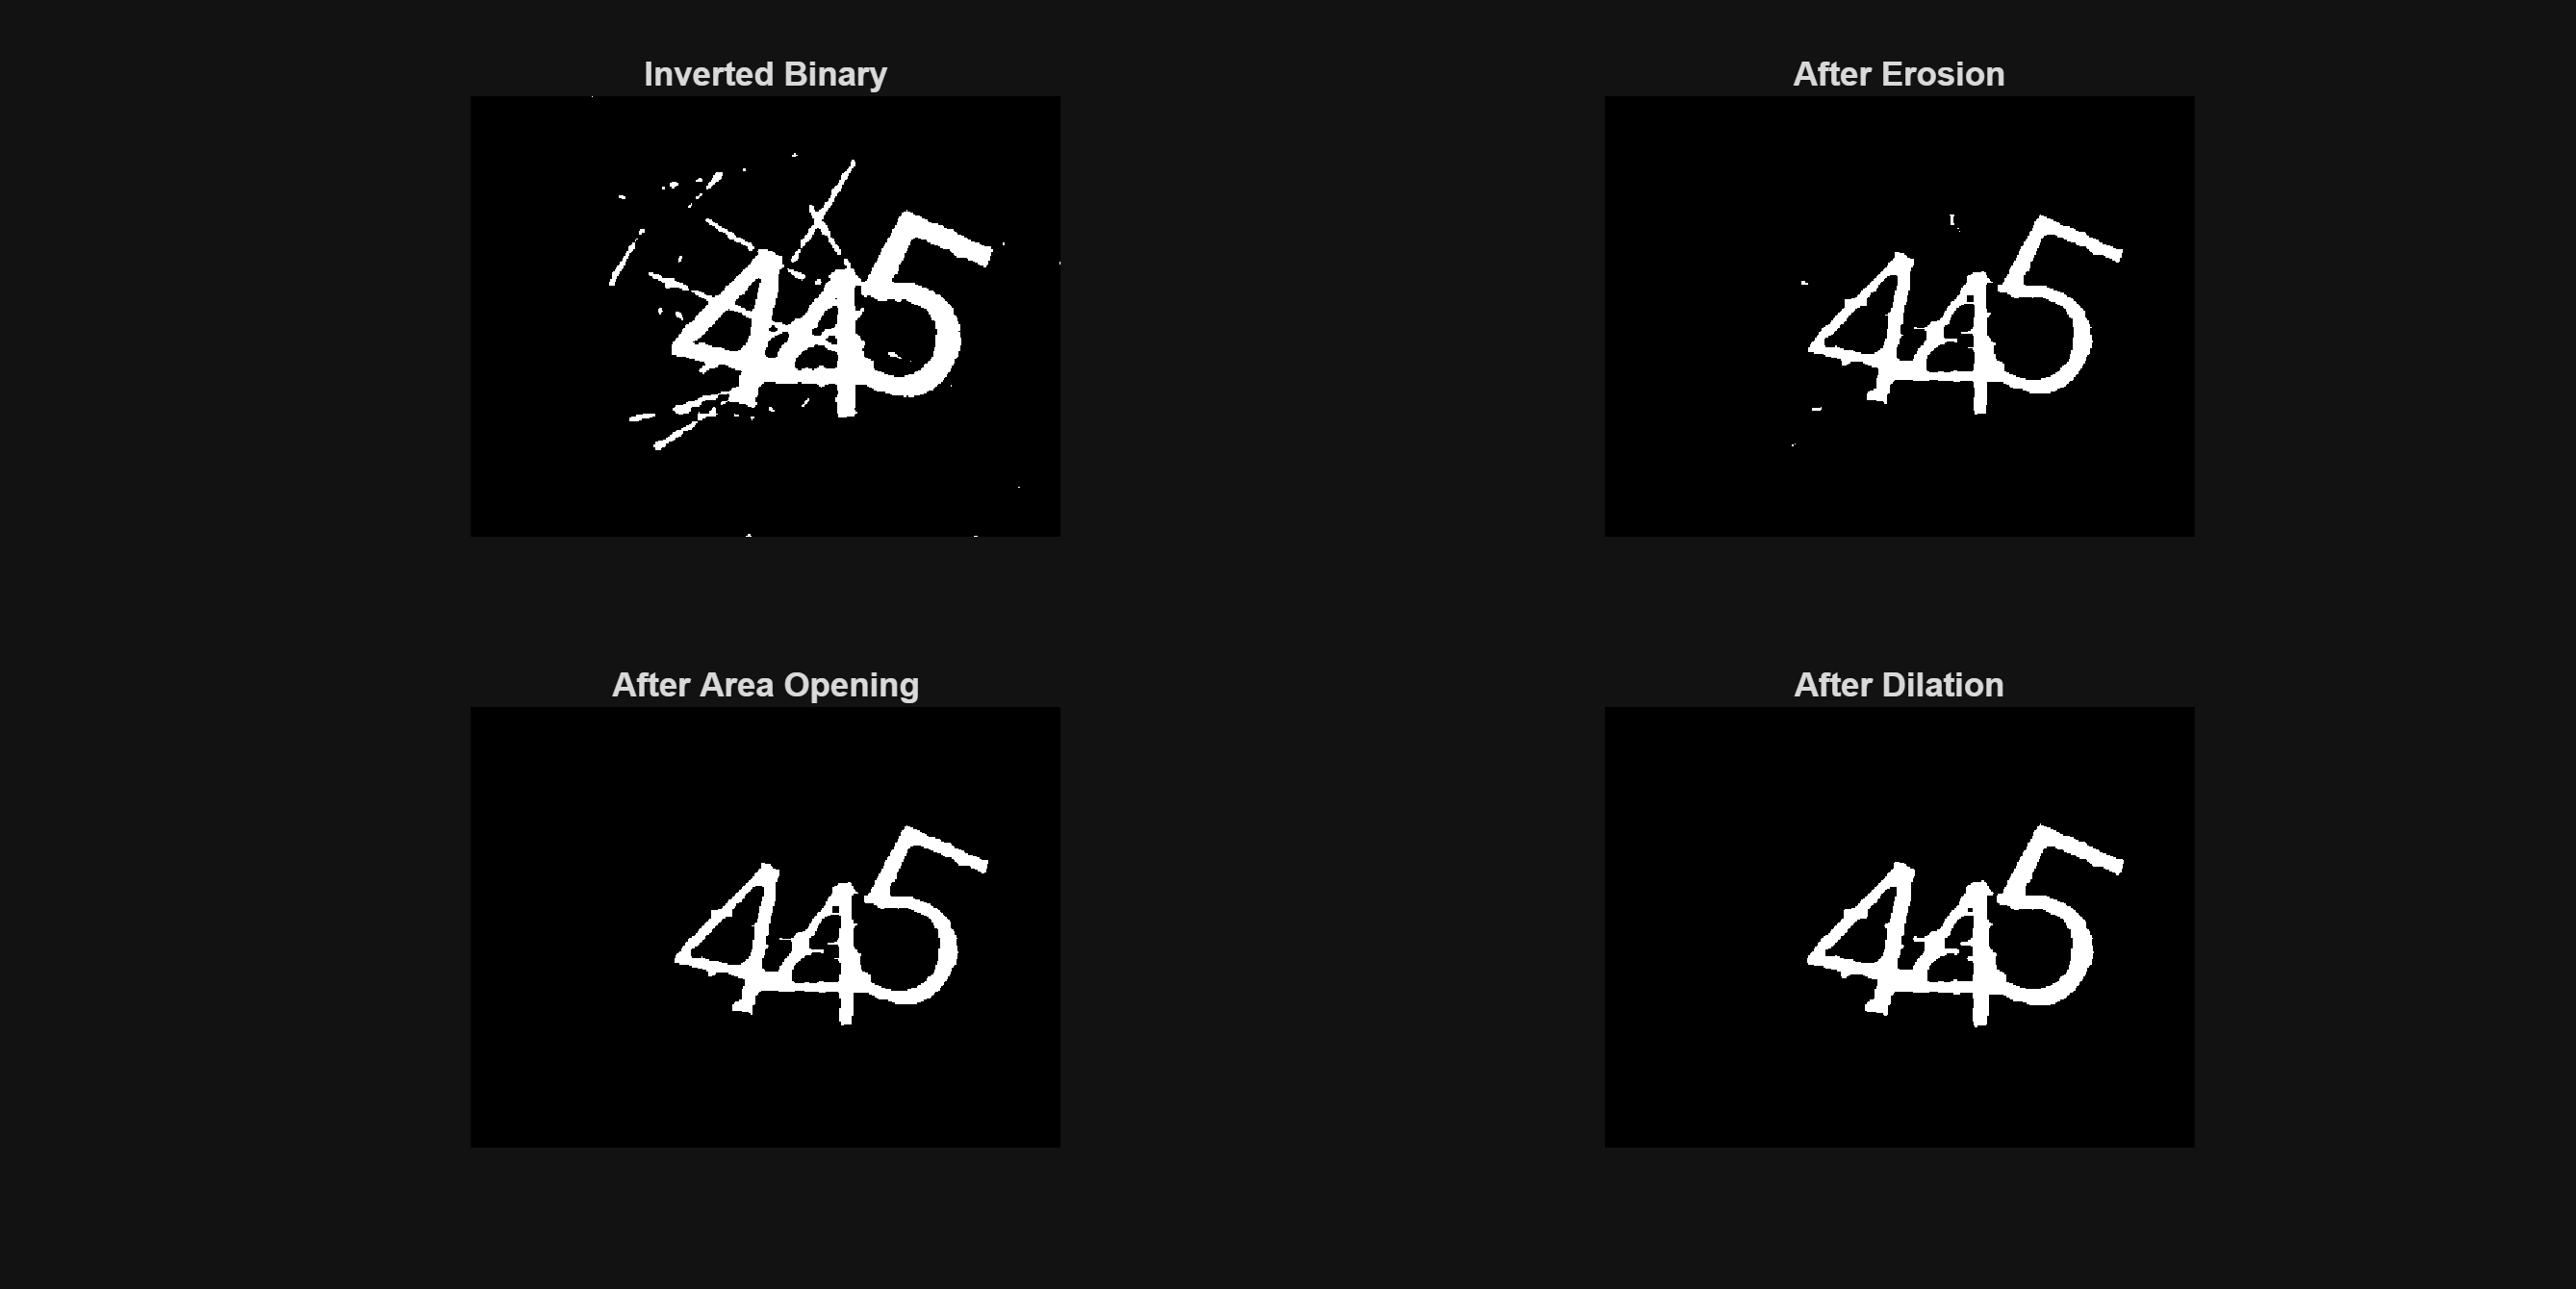

BW = ~BW_otsu;

BW_erode  = imerode(BW, strel('disk',3));
BW_area   = bwareaopen(BW_erode,150);
BW_dilate = imdilate(BW_area, strel('disk',1));

figure('Name','Step 8: Morphological Processing','Position',[100 100 1200 600]);

subplot(2,2,1);
imshow(BW);
title('Inverted Binary');

subplot(2,2,2);
imshow(BW_erode);
title('After Erosion');

subplot(2,2,3);
imshow(BW_area);
title('After Area Opening');

subplot(2,2,4);
imshow(BW_dilate);
title('After Dilation');

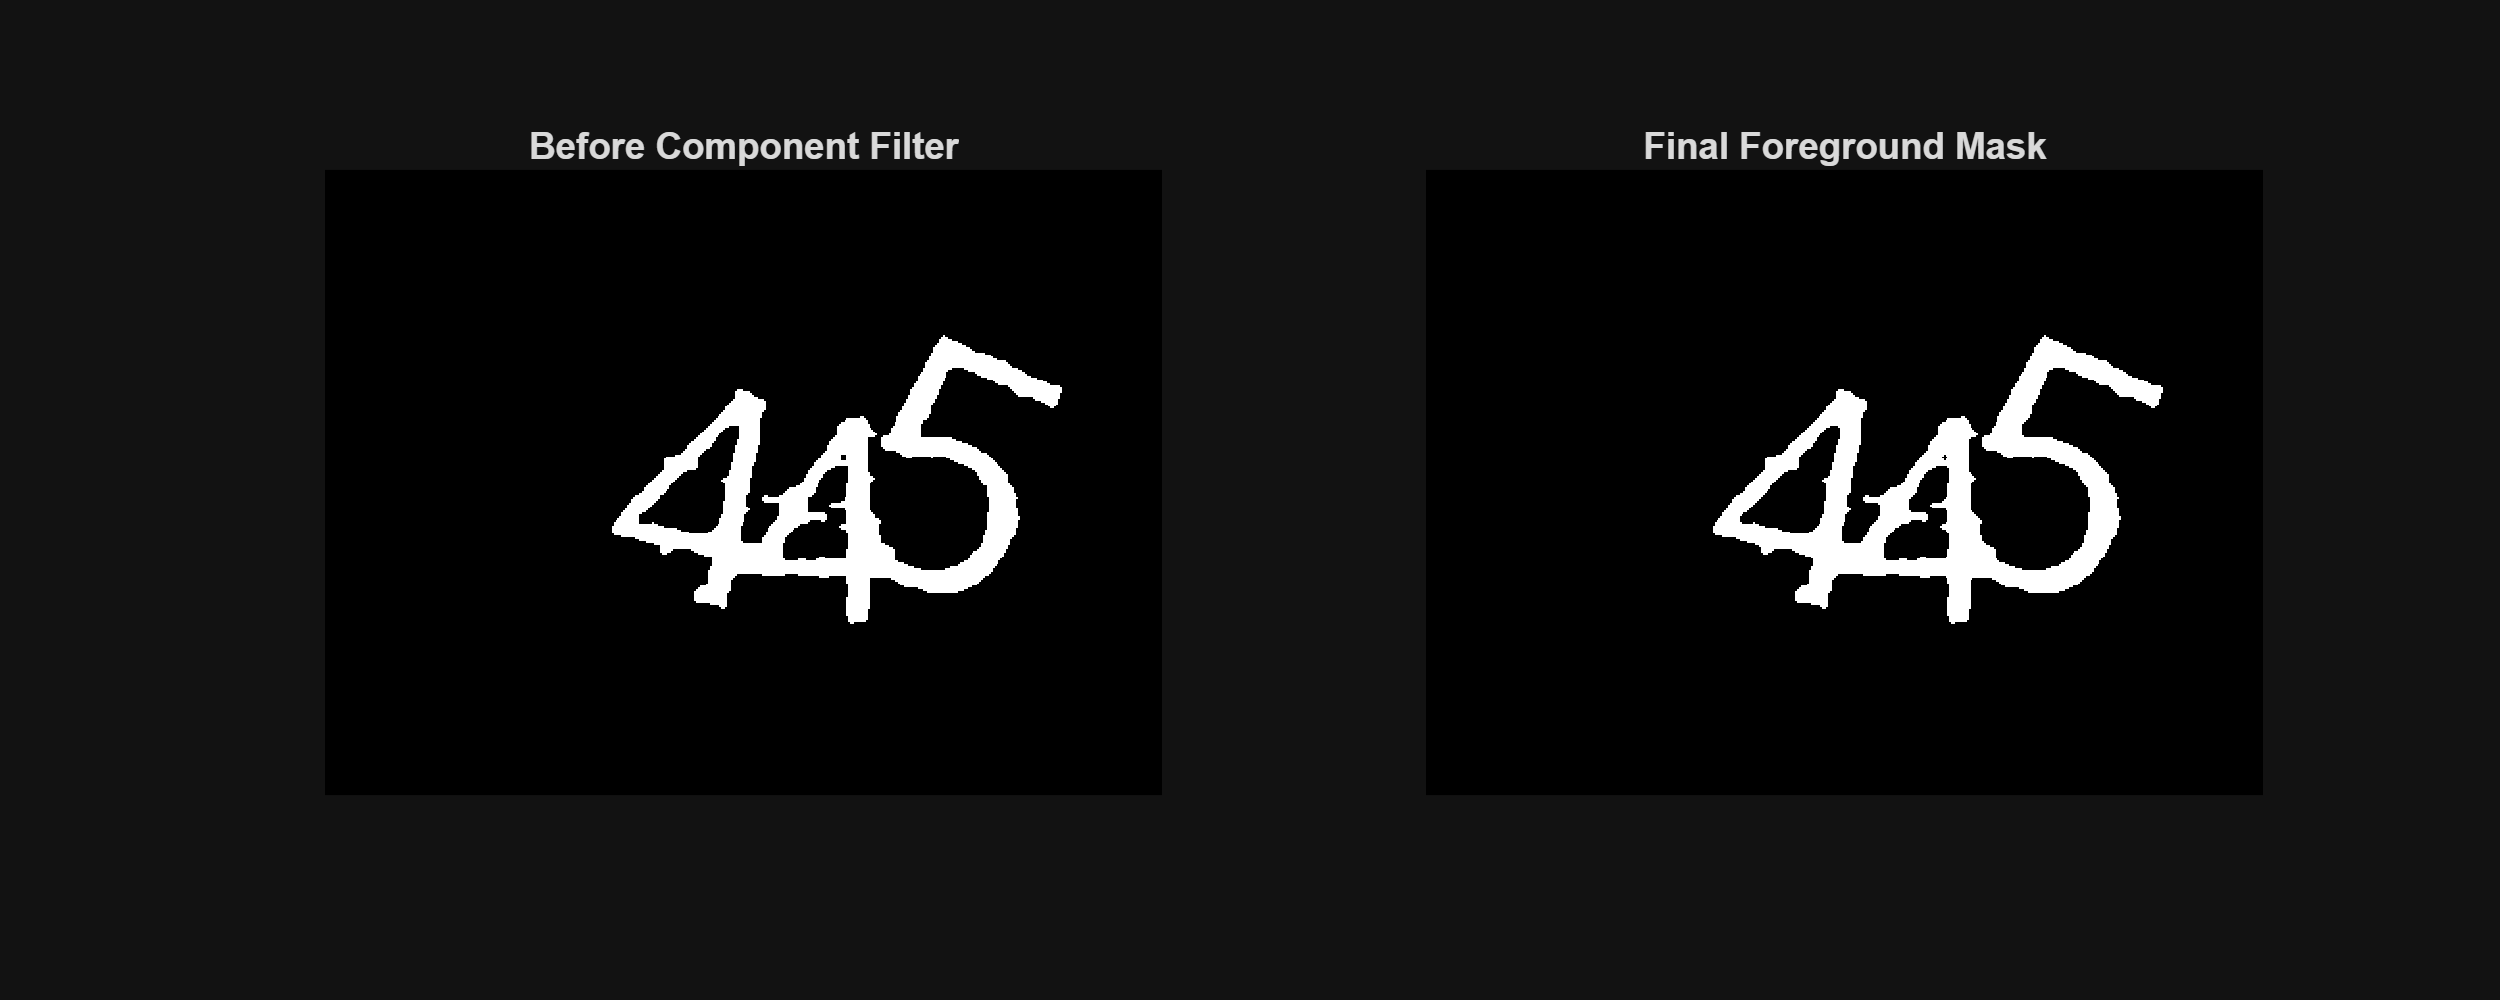

CC = bwconncomp(BW_dilate,8);
stats = regionprops(CC,'Area');

BWfull = false(size(BW_dilate));
keepIdx = find([stats.Area] >= 200);
BWfull(cat(1,CC.PixelIdxList{keepIdx})) = true;

BWfull = imclose(BWfull, strel('disk',1));

figure('Name','Step 9: Component Filtering','Position',[100 100 1000 400]);

subplot(1,2,1);
imshow(BW_dilate);
title('Before Component Filter');

subplot(1,2,2);
imshow(BWfull);
title('Final Foreground Mask');

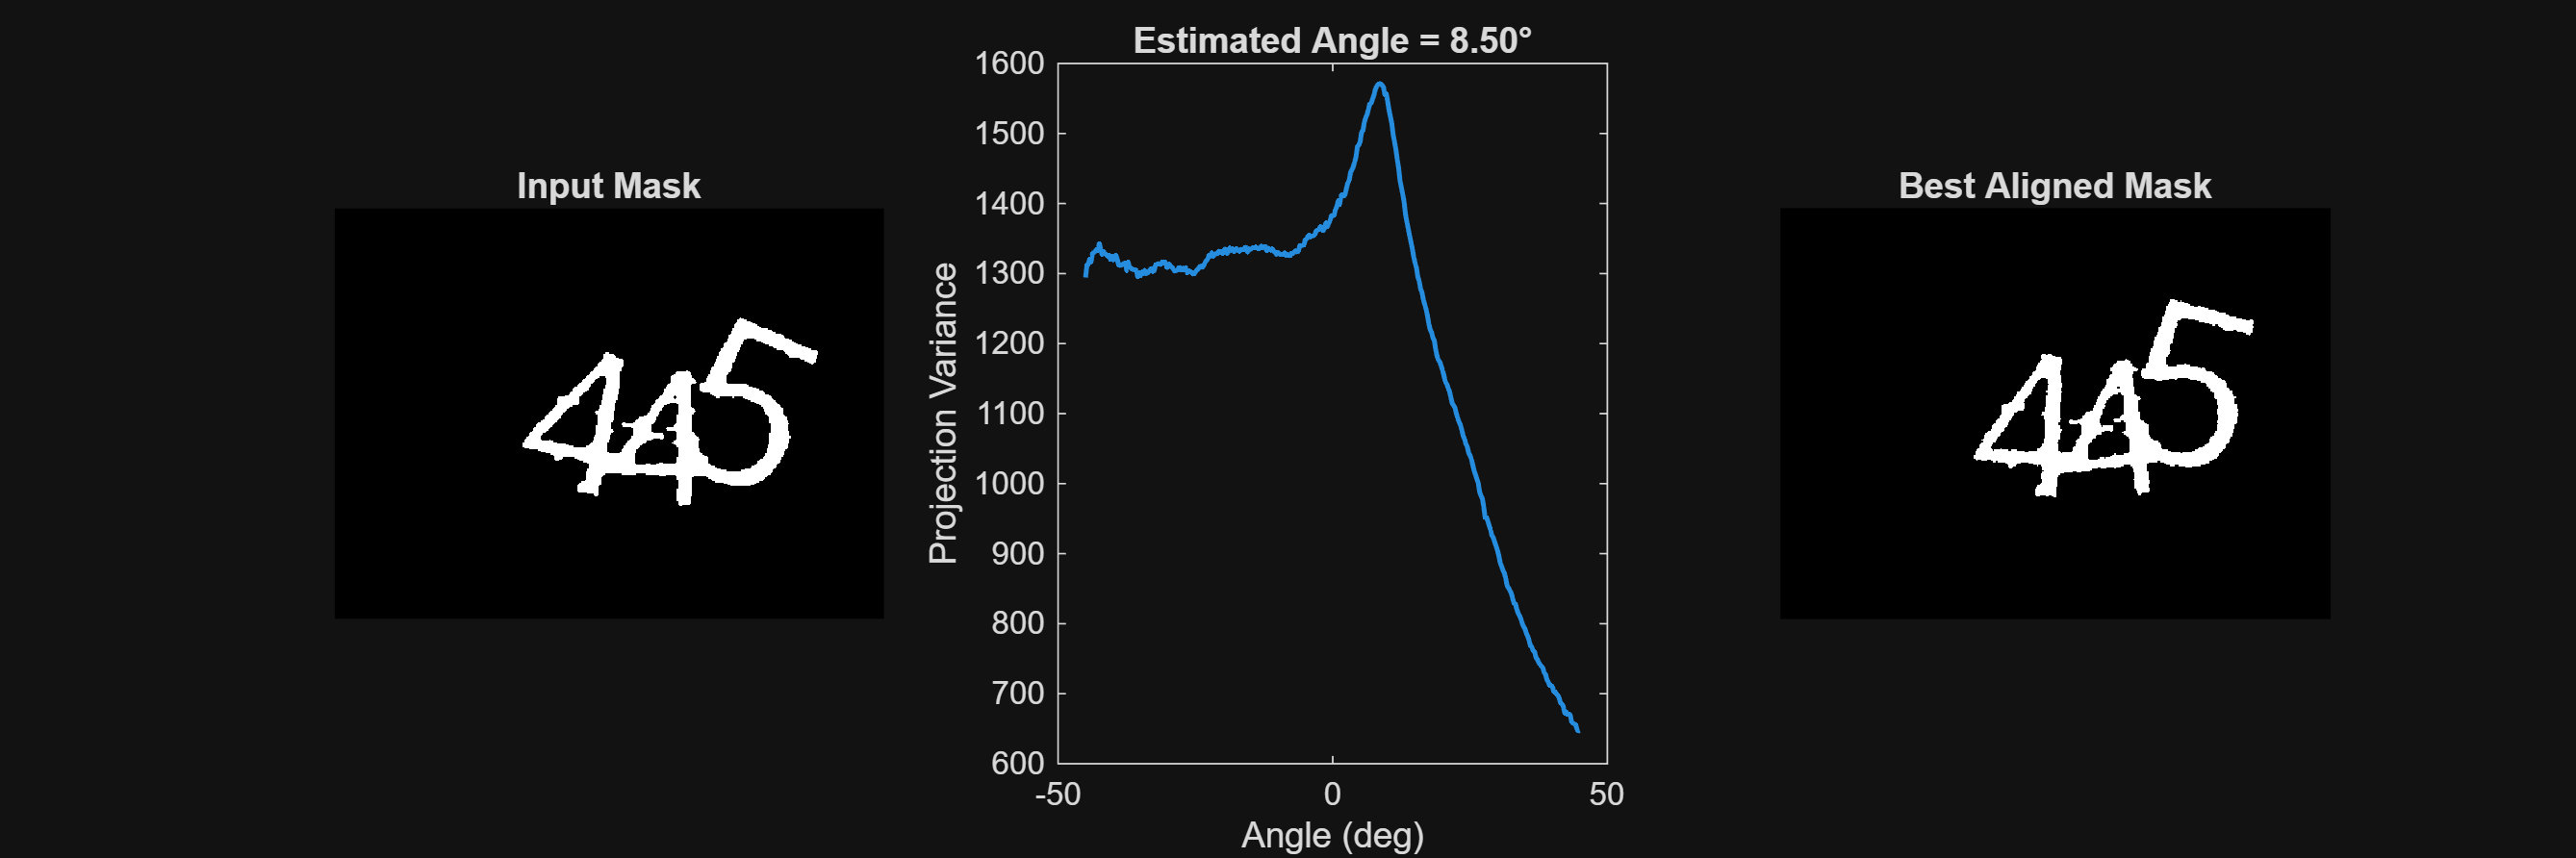

angleRange = 45;
angleStep  = 0.25;
angles = -angleRange:angleStep:angleRange;
scores = zeros(size(angles));

for k = 1:numel(angles)
    BWrot = imrotate(BWfull, angles(k), 'bilinear', 'crop');
    proj = sum(BWrot,2);
    scores(k) = var(proj);
end

[~,idx] = max(scores);
angleDeg = angles(idx);

figure('Name','Step 10: Skew Estimation','Position',[100 100 1200 400]);

subplot(1,3,1);
imshow(BWfull);
title('Input Mask');

subplot(1,3,2);
plot(angles,scores,'LineWidth',1.5);
xlabel('Angle (deg)');
ylabel('Projection Variance');
title(sprintf('Estimated Angle = %.2f°',angleDeg));

subplot(1,3,3);
BWrot_best = imrotate(BWfull, angleDeg, 'bilinear', 'crop');
imshow(BWrot_best);
title('Best Aligned Mask');

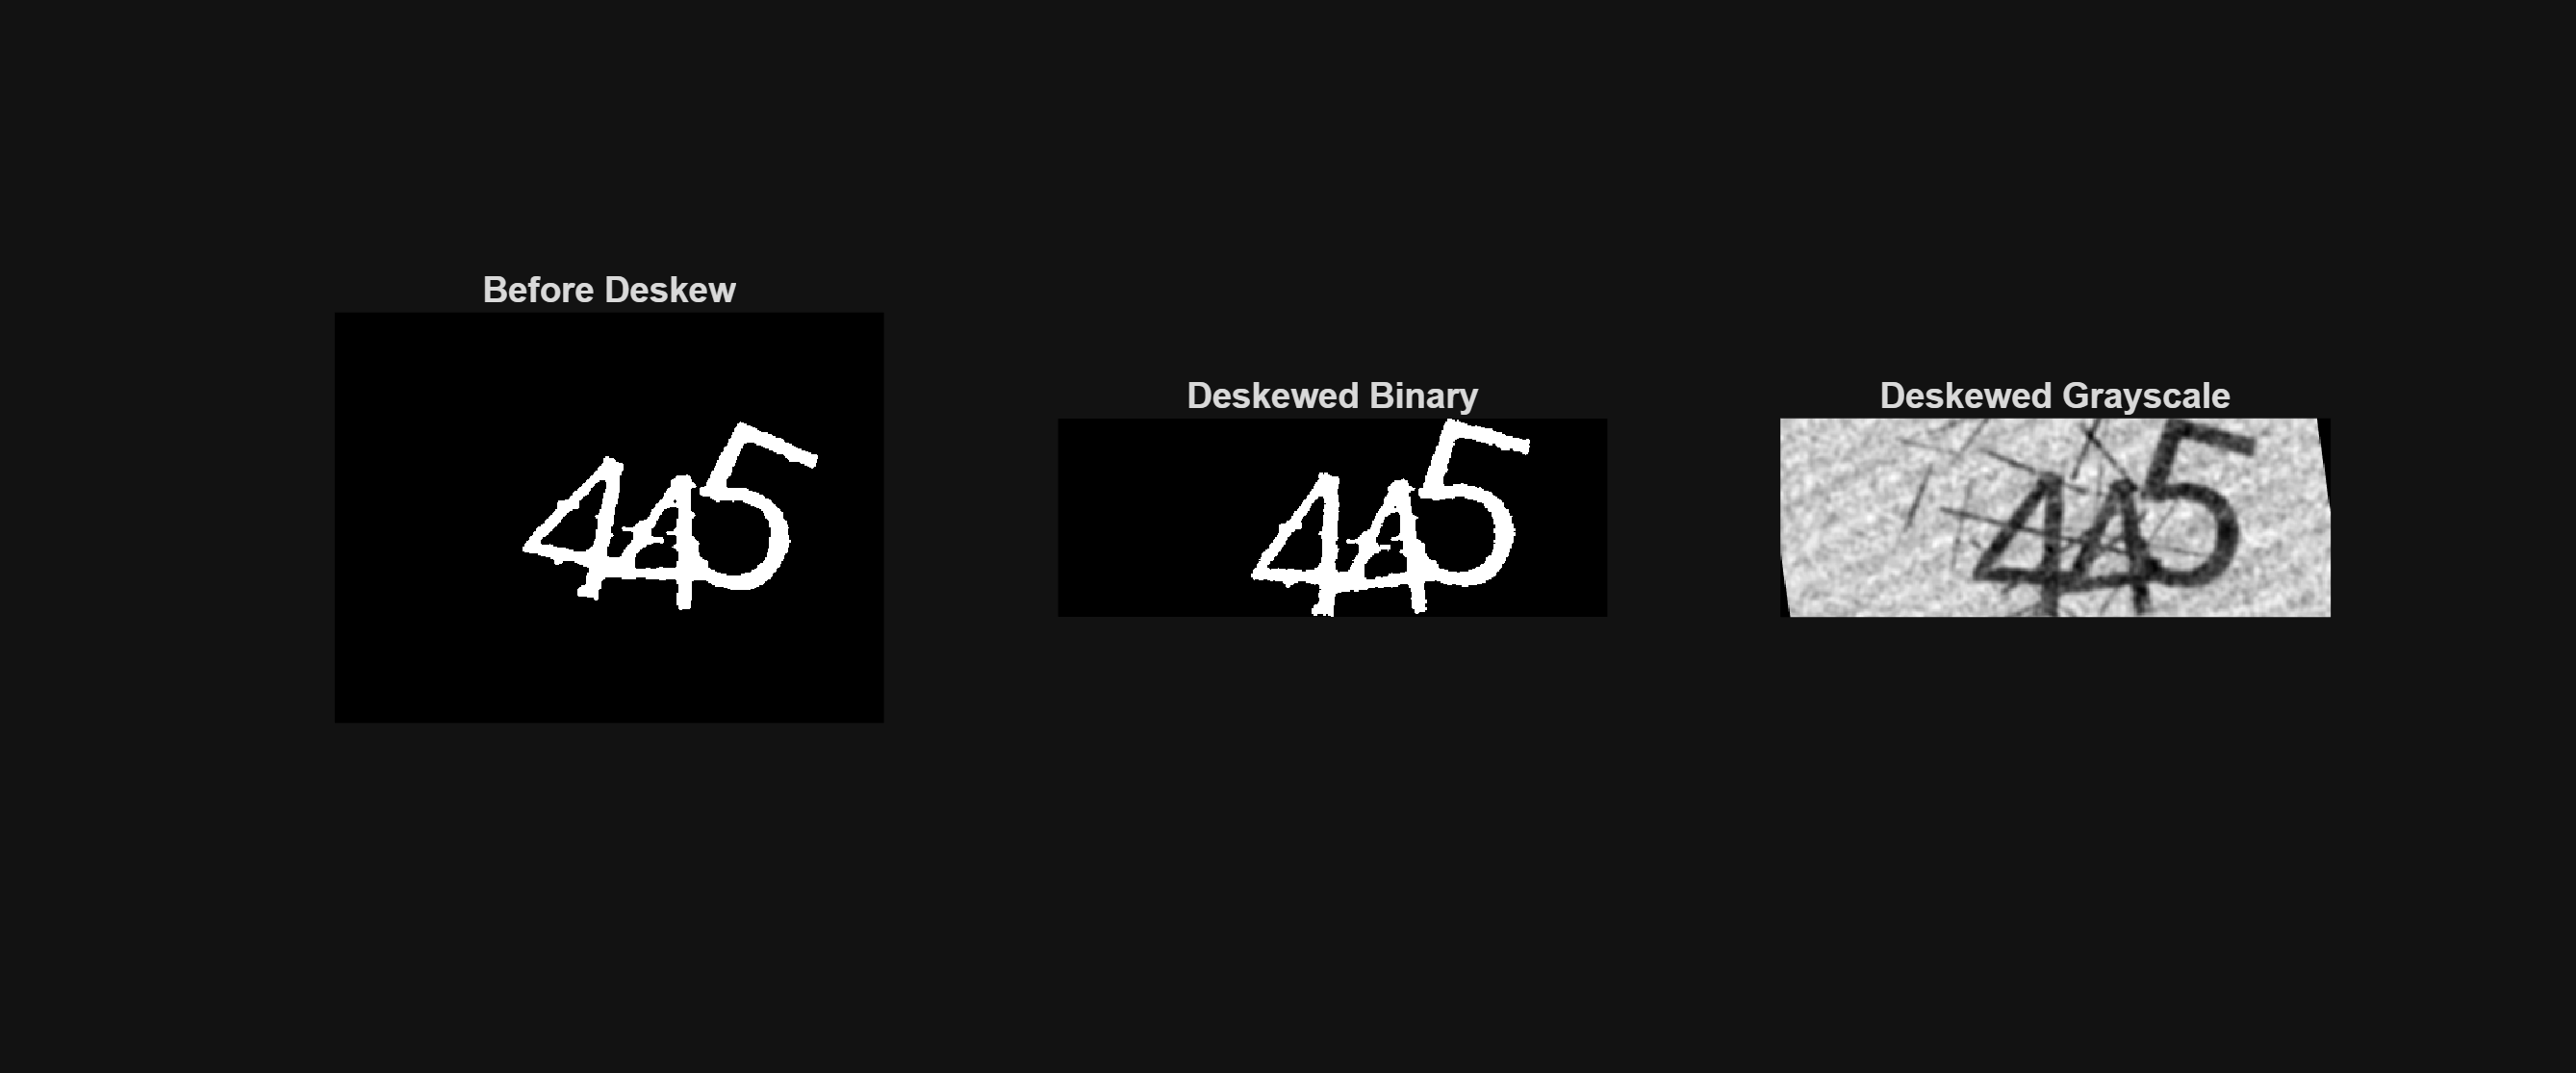

BWdeskew = imrotate(BWfull, angleDeg, 'bilinear', 'crop');
Gdeskew  = imrotate(Gclean, angleDeg, 'bilinear', 'crop');

rows = any(BWdeskew,2);
BWdeskew = BWdeskew(rows,:);
Gdeskew  = Gdeskew(rows,:);

figure('Name','Step 11: Final Deskewed Output','Position',[100 100 1200 500]);

subplot(1,3,1);
imshow(BWfull);
title('Before Deskew');

subplot(1,3,2);
imshow(BWdeskew);
title('Deskewed Binary');

subplot(1,3,3);
imshow(Gdeskew,[]);
title('Deskewed Grayscale');

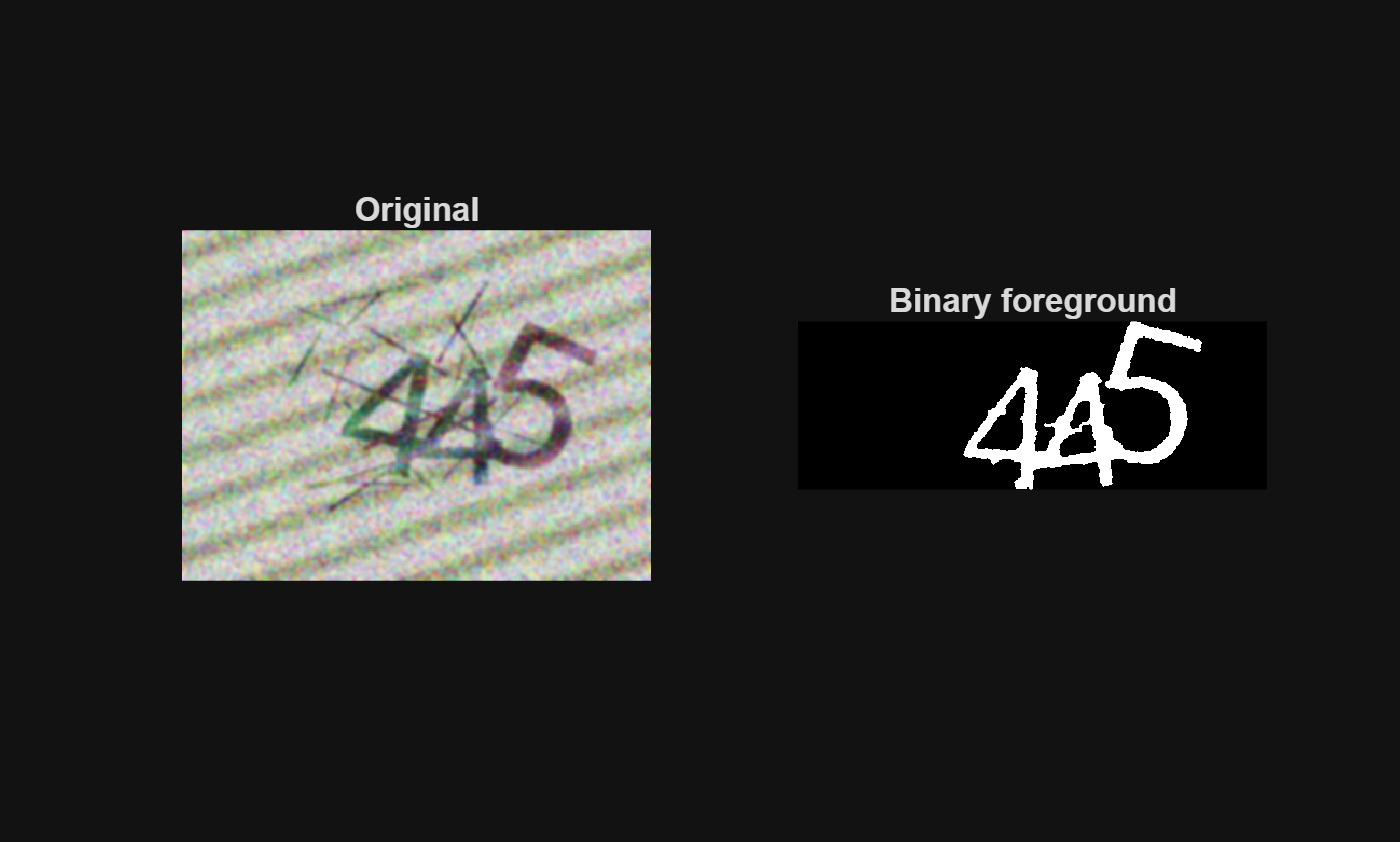

[BWfull, Gclean, info] = preprocessCaptcha(I);

figure;
subplot(1,2,1), imshow(I), title('Original')
subplot(1,2,2), imshow(BWfull), title('Binary foreground')

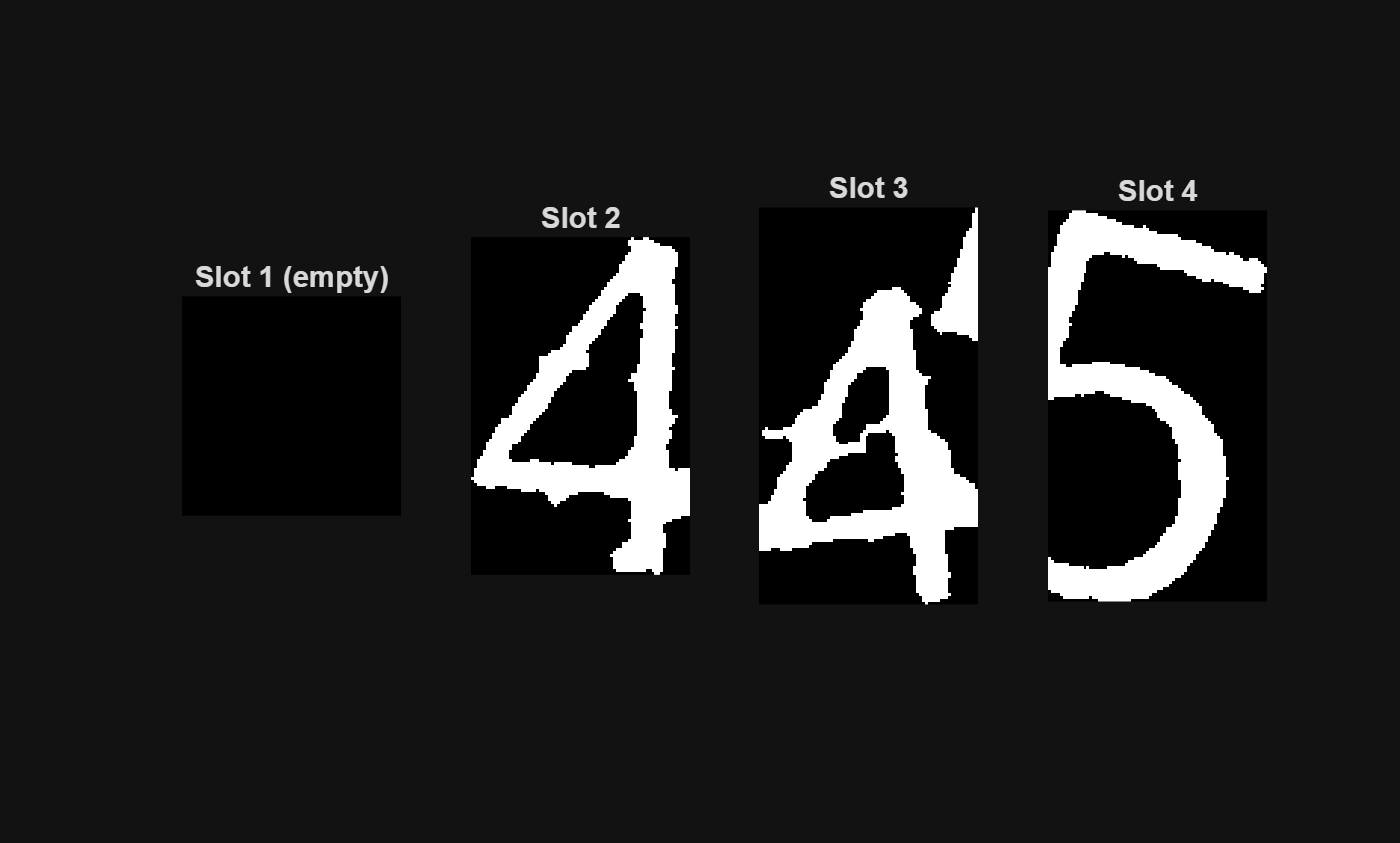

% Run feature extraction
[X4, patches, infoFeat] = Full_FeatureExtraction(I);

% Visualize each digit slot
figure;
for k = 1:4
    subplot(1,4,k);
    if ~isempty(patches{k})
        imshow(patches{k}); title(sprintf('Slot %d', k));
    else
        imshow(zeros(28,28)); title(sprintf('Slot %d (empty)', k));
    end
end

S = myclassifier(I)

S =      0     4     4     5
